%addpath 'iwave\development\matlab'

load_parameters

t_end = 1; % secs
t = 0 : t_step : t_end;

%% generate signal and noise
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);

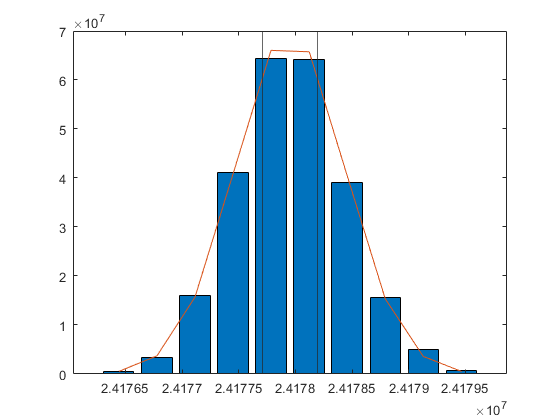

figure
[counts, centres] = hist(f_axion);
bar(centres, counts)
%set(gca, 'yscale','log')
band = [f_a - axion_linewidth/2, f_a + axion_linewidth/2];
xline(band)
hold on
plot(centres, gaussmf(centres, [axion_linewidth f_a])*7e7)

inside = band(1) < f_axion & f_axion < band(2);
sum(inside)/length(f_axion)

ans = 0.3810